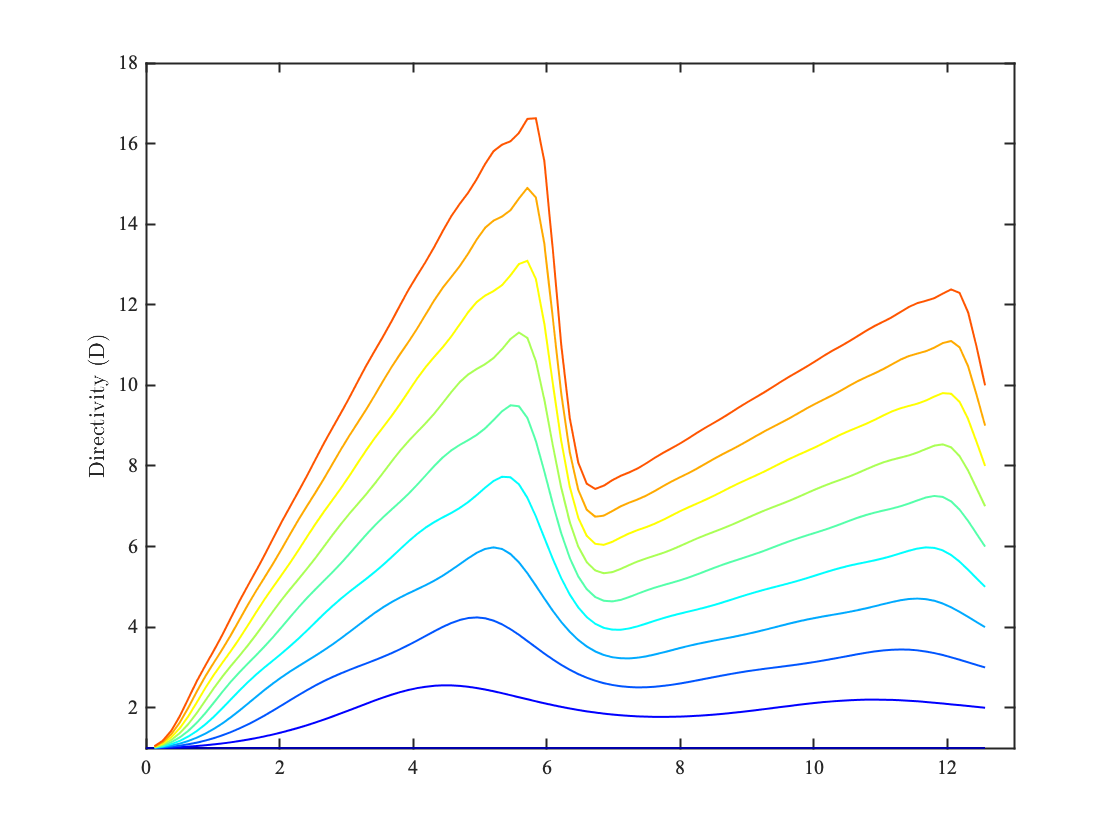

N = linspace(1,10,10);
alpha = 0;
kd = linspace(0, 4*pi, 100);

sum = zeros(length(N),length(kd));
 for i = 2 : max(N)
    for j = 1 : length(kd)
        for m = 1 : i-1
            sum(i,j) = sum(i,j) + (i-m)./(m.*kd(j)).*sin(m*kd(j)).*cos(m*alpha);
        end
    end
end
D = 1./N + 2./N.^2.*sum';
h = plot(kd, 1./D);
ii = (1:10)';
set(h, {'color'}, num2cell(jet(length(ii)), 2));
set(gcf,'Color','white'); % Set background color to white
set (gca,'FontName','times new roman') % Set axes fonts to Times New Roman
ax = gca;
ylabel('Directivity (D)','Interpreter','latex'); % y-axis label
box on %

xlim([0 13])
ylim([1 18])


ax2 = gca;

% matlab2tikz('directivity.tex','standalone',true)
